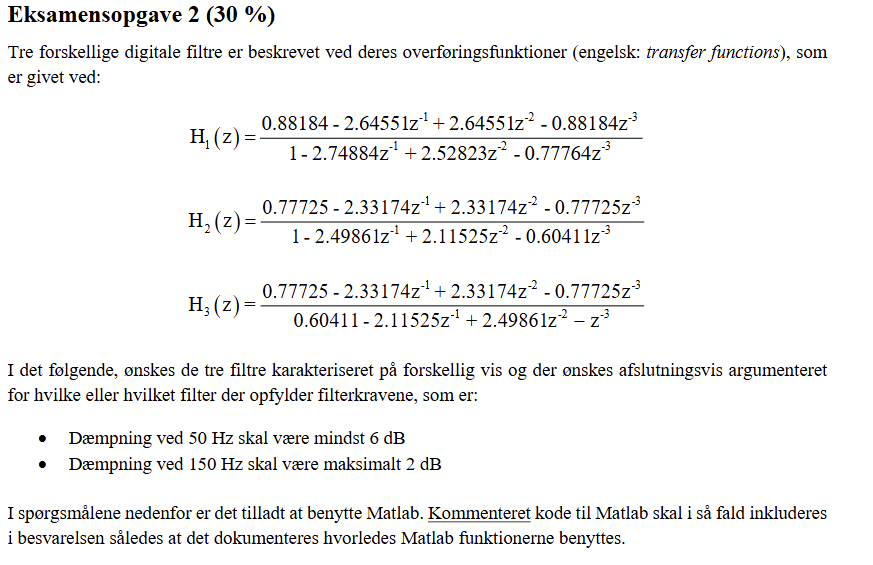

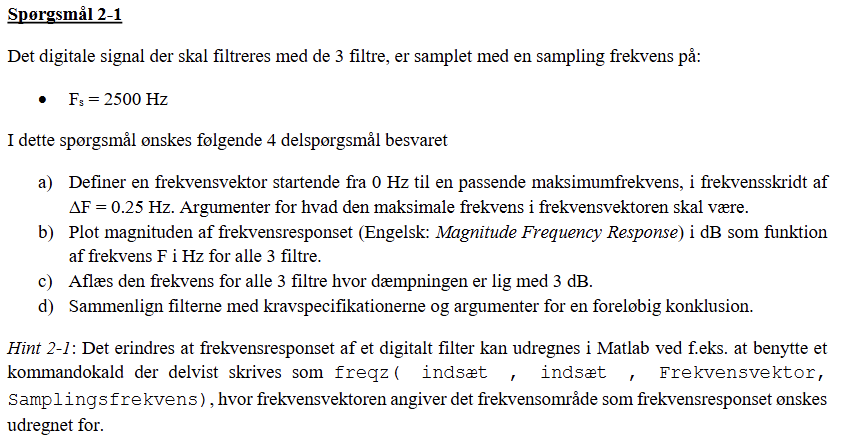

clear
Fs = 2500;
Ts = 1/Fs

Ts = 4.0000e-04

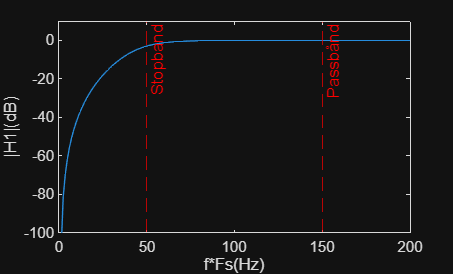


Fstop = 50; 
Fpass = 150;
AsdB = 6; 
ApdB = 2; 

% a)
deltaF = 0.25; 
Freq = [0:deltaF:Fs/2];

%vi har defineret frekvensvektoren op til den maksimale frekvens som er
%Fs/2 fordi det er den maksimale frekvens der kan køres uden aliasering

%b) 
%Filter 1 
b1 = [0.88184,-2.64551,2.64551,-0.88184];
a1 = [1,-2.74884,2.52823,-0.77764];
[H1,freq1] = freqz(b1,a1,1024,Fs);

%Filter 2
b2 = [0.77725,-2.33174,2.33174,-0.77725];
a2 = [1,-2.49861,2.11525,-0.60411];
[H2,freq2] = freqz(b2,a2,1024,Fs);

%Filter 3 
b3 = [0.77725,-2.33174, 2.33174, -0.77725];
a3 = [0.60411, -2.11525, 2.49861, -1];
[H3,freq3] = freqz(b3,a3,1024,Fs);


%plot 1
plot(freq1,20*log10(abs(H1)));
xlabel('f*Fs(Hz)')
ylabel(['|H1|(dB)'])
xline(Fstop,'--r', "Stopband") % indsætter en linje for stopbåndsfrek 
xline(Fpass,'--r', "Passbånd") % indsætter en linje for pasbåndsfrek 
xlim([0,200])
ylim([-100,10])
hold off

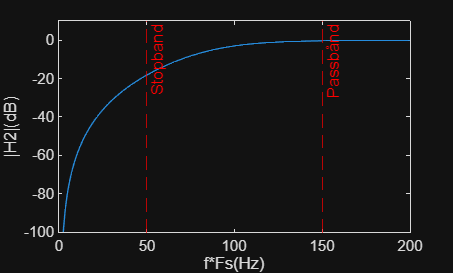

%plot2
plot(freq2,20*log10(abs(H2)));
xlabel('f*Fs(Hz)')
ylabel(['|H2|(dB)'])
xline(Fstop,'--r', "Stopband") % indsætter en linje for stopbåndsfrek 
xline(Fpass,'--r', "Passbånd") % indsætter en linje for pasbåndsfrek 
xlim([0,200])
ylim([-100,10])
hold off 

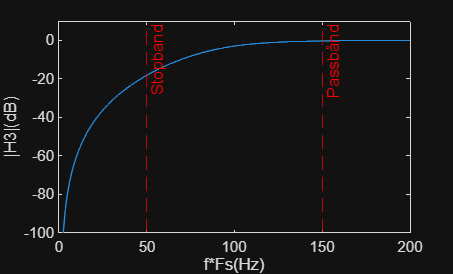

%plot3
plot(freq3,20*log10(abs(H3)));
xlabel('f*Fs(Hz)')
ylabel(['|H3|(dB)'])
xline(Fstop,'--r', "Stopband") % indsætter en linje for stopbåndsfrek 
xline(Fpass,'--r', "Passbånd") % indsætter en linje for pasbåndsfrek 
xlim([0,200])
ylim([-100,10])
hold off


%Opgave 2.2 


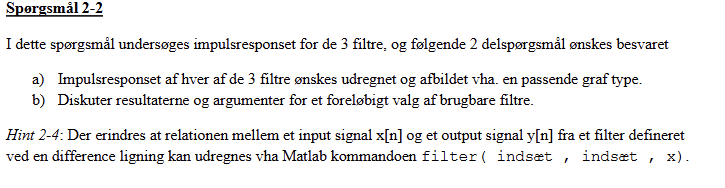

%definerer n vektoren og enhedspulsen som skal puttes i filtrene
n = [-10:1:40];
Unit_pulse = (n==0);
% filter 1 
h1 = filter(b1,a1,Unit_pulse)

h1 =          0         0         0         0         0         0         0         0         0         0    0.8818   -0.2215   -0.1928   -0.1661   -0.1413   -0.1186   -0.0977   -0.0788   -0.0616   -0.0463   -0.0328   -0.0208   -0.0105   -0.0016    0.0059    0.0121    0.0171    0.0210    0.0239    0.0259    0.0271    0.0277    0.0276    0.0270    0.0259    0.0245    0.0229    0.0210    0.0190    0.0168    0.0147    0.0125    0.0103    0.0083    0.0063    0.0044    0.0027    0.0011   -0.0004   -0.0016


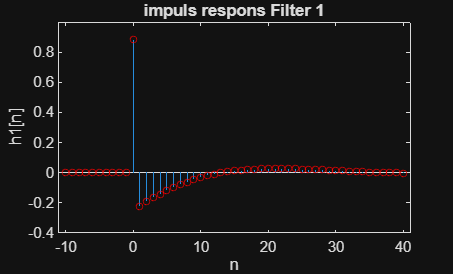

stem(n,h1,'lineWidth',0.4,'MarkerSize',4,'MarkerEdgeColor','red')
xlabel('n')
ylabel(['h1[n]'])
title('impuls respons Filter 1')

%filter2

h2 = filter(b2,a2,Unit_pulse)

h2 =          0         0         0         0         0         0         0         0         0         0    0.7772   -0.3897   -0.2860   -0.1981   -0.1253   -0.0670   -0.0218    0.0113    0.0341    0.0480    0.0546    0.0556    0.0524    0.0462    0.0383    0.0296    0.0209    0.0126    0.0053   -0.0008   -0.0057   -0.0092   -0.0116   -0.0128   -0.0131   -0.0126   -0.0115   -0.0101   -0.0084   -0.0066   -0.0049   -0.0033   -0.0019   -0.0006    0.0003    0.0011    0.0016    0.0019    0.0020    0.0020


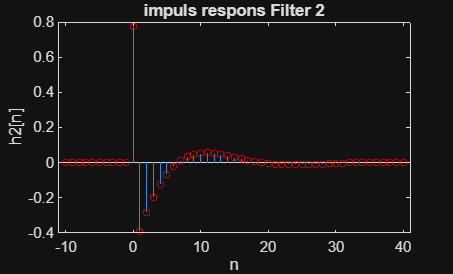

stem(n,h2,'lineWidth',0.4,'MarkerSize',4,'MarkerEdgeColor','red')
xlabel('n')
ylabel(['h2[n]'])
title('impuls respons Filter 2')

%filter 3 
h3 = filter(b3,a3,Unit_pulse)

h3 = 1.0e+03 *

         0         0         0         0         0         0         0         0         0         0    0.0013    0.0006    0.0008    0.0010    0.0012    0.0014    0.0016    0.0019    0.0022    0.0026    0.0031    0.0038    0.0047    0.0059    0.0076    0.0098    0.0128    0.0168    0.0221    0.0292    0.0385    0.0507    0.0666    0.0872    0.1138    0.1481    0.1922    0.2488    0.3213    0.4143    0.5334    0.6861    0.8819    1.1331    1.4558    1.8706    2.4042    3.0911    3.9761    5.1167


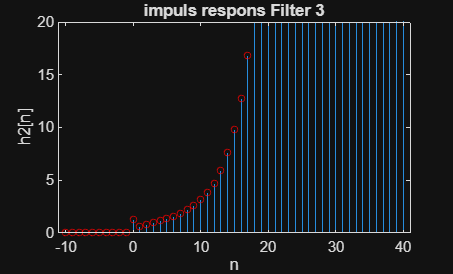

stem(n,h3,'lineWidth',0.4,'MarkerSize',4,'MarkerEdgeColor','red')
ylim([0,20]);
xlabel('n')
ylabel(['h2[n]'])
title('impuls respons Filter 3')

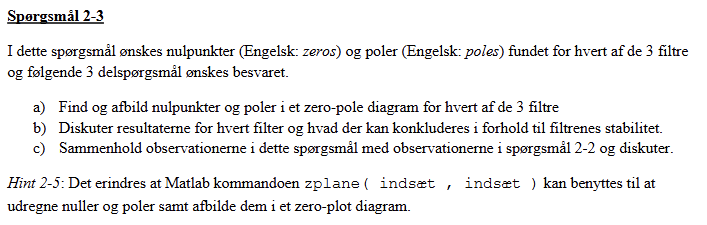

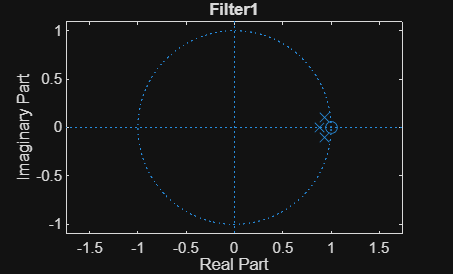


zplane(b1,a1)
title('Filter1');

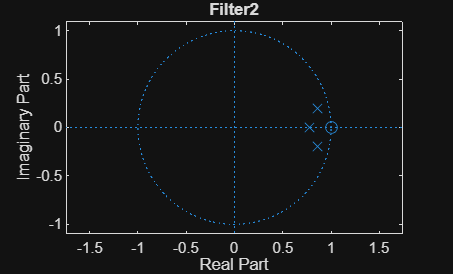

zplane(b2,a2)
title('Filter2');

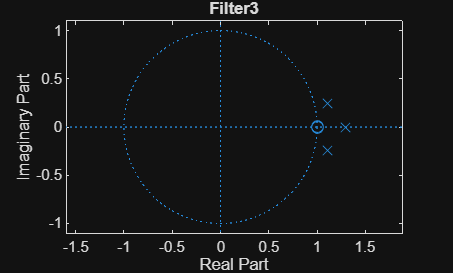

zplane(b3,a3)
title('Filter3');

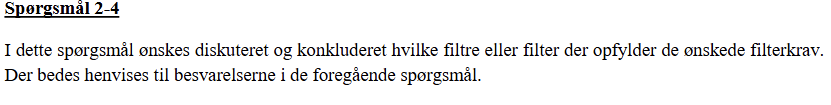

Opgave 3

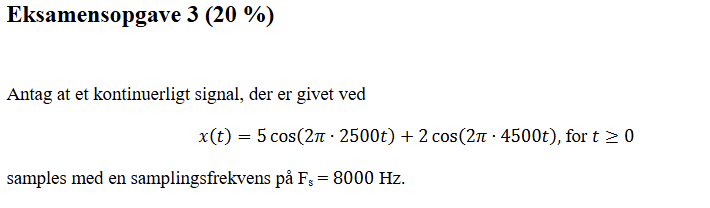

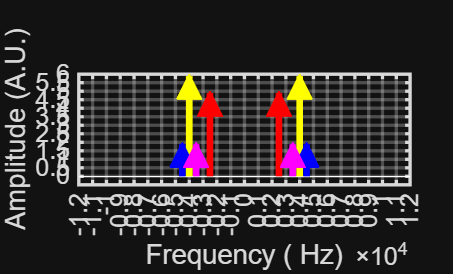

%==========================================================================
%
%   Technical University of Denmark
%
%   62743 Digital Signal Processing
%
%   Template for manually sketching spectra
%   The script can be adapted to become a function
%
%   Lars Søgaard Rishøj + Anders T. Clausen
%
%   2023
%
%==========================================================================

clear all
close all
clc

%==========================================================================
%
%   Plot to sketch spectrum of signal
%
%==========================================================================

%% Generate empty plot with no arrows

% USER-DEFINED AXIS INFORMATION
xmax =12000;                              % Set maximum for x-axis
xstep = 1000;                              % Set steps for x-axis
ymax = 6;                               % Set maximum for y-axis
ystep = 0.5;                            % Set steps for y-axis

% Define vectors - do not change
xaxis = [-xmax:xstep:xmax];
yaxis = zeros(size(xaxis));
yindex = [0:ystep:ymax];

% Generate plot - do not change
figure(1)
plot(xaxis,yaxis,'w')                   % Plot graph with no content
set(gca,'FontSize',15,'Fontname', 'Arial','linewidth',2)
xlabel('Frequency ( Hz)')
ylabel('Amplitude (A.U.)')
set(gca,'XTick',xaxis);
set(gca,'YTick',yindex);
pbaspect([3,1,1])
ylim([-0.5 ymax])
grid on
hold on

%% Generate arrows


%-Fs/2 og Fs/2
% Arrow block 1 - discrete spectral component 1
    x_pos = -4000;                        % set x-axis position
    y_start = 0;                        % set y-axis start
    y_end = 6;                          % set y-axis end
    anArrow = annotation('arrow');
    anArrow.Parent = gca;
    anArrow.X = [x_pos,x_pos];
    anArrow.Y = [y_start ,y_end];
    anArrow.Color = 'yellow';              % set colour of arrow
    anArrow.LineWidth = 4;
    anArrow.HeadLength = 15;
    anArrow.HeadWidth = 15;
    anArrow.HeadStyle = 'plain';
    

% Arrow block 2 - discrete spectral component 2
    x_pos = 4000;                        % set x-axis position
    y_start = 0;                        % set y-axis start
    y_end = 6;                        % set y-axis end
    anArrow = annotation('arrow');
    anArrow.Parent = gca;
    anArrow.X = [x_pos,x_pos];
    anArrow.Y = [y_start ,y_end];
    anArrow.Color = 'yellow';             % set colour of arrow
    anArrow.LineWidth = 4;
    anArrow.HeadLength = 15;
    anArrow.HeadWidth = 15;
    anArrow.HeadStyle = 'plain';

% Copy arrow block for each addditional arrow needed in plot 


%frekvens 1
% Arrow block 1 - discrete spectral component 1
    x_pos = -2500;                        % set x-axis position
    y_start = 0;                        % set y-axis start
    y_end = 5;                          % set y-axis end
    anArrow = annotation('arrow');
    anArrow.Parent = gca;
    anArrow.X = [x_pos,x_pos];
    anArrow.Y = [y_start ,y_end];
    anArrow.Color = 'red';              % set colour of arrow
    anArrow.LineWidth = 4;
    anArrow.HeadLength = 15;
    anArrow.HeadWidth = 15;
    anArrow.HeadStyle = 'plain';
    

% Arrow block 2 - discrete spectral component 2
    x_pos = 2500;                        % set x-axis position
    y_start = 0;                        % set y-axis start
    y_end = 5;                        % set y-axis end
    anArrow = annotation('arrow');
    anArrow.Parent = gca;
    anArrow.X = [x_pos,x_pos];
    anArrow.Y = [y_start ,y_end];
    anArrow.Color = 'red';             % set colour of arrow
    anArrow.LineWidth = 4;
    anArrow.HeadLength = 15;
    anArrow.HeadWidth = 15;
    anArrow.HeadStyle = 'plain';


%frekvens 2
% Arrow block 1 - discrete spectral component 1
    x_pos = -4500;                        % set x-axis position
    y_start = 0;                        % set y-axis start
    y_end = 2;                          % set y-axis end
    anArrow = annotation('arrow');
    anArrow.Parent = gca;
    anArrow.X = [x_pos,x_pos];
    anArrow.Y = [y_start ,y_end];
    anArrow.Color = 'blue';              % set colour of arrow
    anArrow.LineWidth = 4;
    anArrow.HeadLength = 15;
    anArrow.HeadWidth = 15;
    anArrow.HeadStyle = 'plain';
    
% Frekvens 2 
% Arrow block 2 - discrete spectral component 2
    x_pos = 4500;                        % set x-axis position
    y_start = 0;                        % set y-axis start
    y_end = 2;                        % set y-axis end
    anArrow = annotation('arrow');
    anArrow.Parent = gca;
    anArrow.X = [x_pos,x_pos];
    anArrow.Y = [y_start ,y_end];
    anArrow.Color = 'blue';             % set colour of arrow
    anArrow.LineWidth = 4;
    anArrow.HeadLength = 15;
    anArrow.HeadWidth = 15;
    anArrow.HeadStyle = 'plain';


%frekvens 2 spejling 
% Arrow block 1 - discrete spectral component 1
    x_pos = -3500;                        % set x-axis position
    y_start = 0;                        % set y-axis start
    y_end = 2;                          % set y-axis end
    anArrow = annotation('arrow');
    anArrow.Parent = gca;
    anArrow.X = [x_pos,x_pos];
    anArrow.Y = [y_start ,y_end];
    anArrow.Color = 'm';              % set colour of arrow
    anArrow.LineWidth = 4;
    anArrow.HeadLength = 15;
    anArrow.HeadWidth = 15;
    anArrow.HeadStyle = 'plain';
    
% Frekvens 2 spejling 
% Arrow block 2 - discrete spectral component 2
    x_pos = 3500;                        % set x-axis position
    y_start = 0;                        % set y-axis start
    y_end = 2;                        % set y-axis end
    anArrow = annotation('arrow');
    anArrow.Parent = gca;
    anArrow.X = [x_pos,x_pos];
    anArrow.Y = [y_start ,y_end];
    anArrow.Color = 'm';             % set colour of arrow
    anArrow.LineWidth = 4;
    anArrow.HeadLength = 15;
    anArrow.HeadWidth = 15;
    anArrow.HeadStyle = 'plain';
    hold off

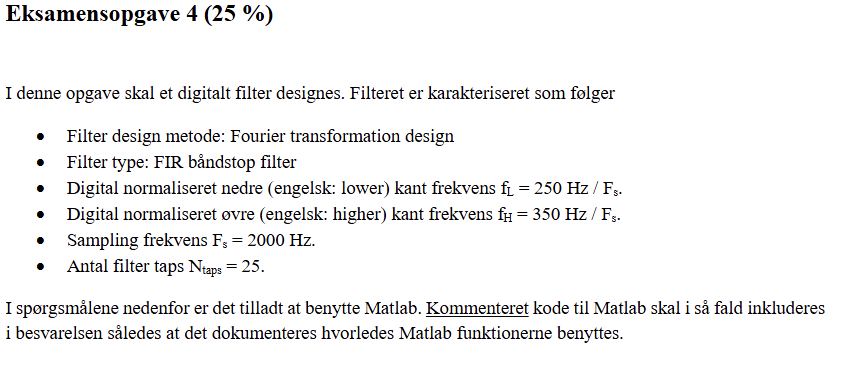

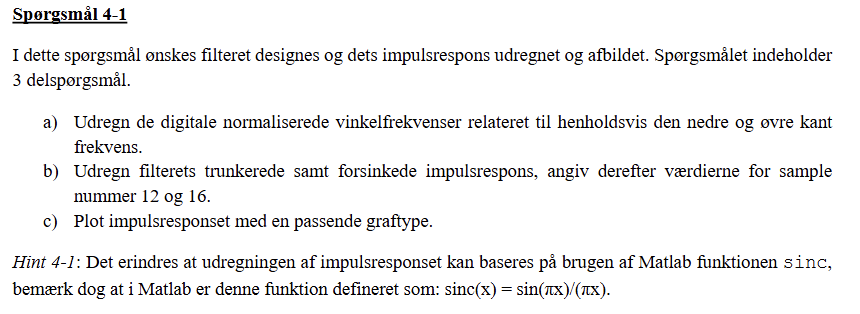

%FIR Båndstop
    
Fs = 2000; 
Ts = 1/Fs; 
fL = 250/Fs;
fH = 350/Fs;

Ntaps = 25; 

%a)
% vi udregner de digitale angulære frekvenser: 
wL = fL*2*pi

wL = 0.7854

wH = fH*2*pi

wH = 1.0996


% wL = 0.7854 -----------resultat--------------
% wH = 1.0996 -----------resultat--------------

%vi udregner M, K og n vektor til at tunkere signalet 
M = Ntaps -1 

M = 24

K = M/2

K = 12

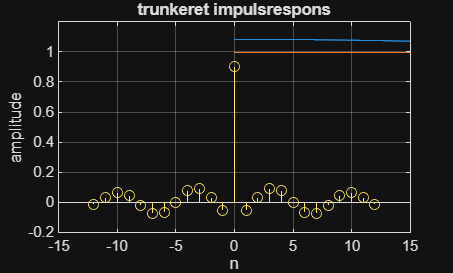

nbp = [-K:1:K];

hi_BS = -(wH/pi)*sinc((nbp*wH)/pi)+(wL/pi)*sinc((nbp*wL)/pi); % for n ikke lig    0 

% her er betingelserne på n == 0 opfyldt også 
h_ideel = hi_BS;               % gælder for alle n
h_ideel(nbp==0) = (pi - wH + wL)/pi;     % KUN n = 0 rettes

%den trunkerede
stem(nbp,h_ideel)
xlim([-15,15])
xlabel('n')
ylabel(['amplitude'])
grid on
title('trunkeret impulsrespons')
hold off

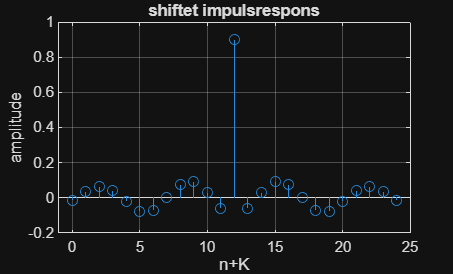

%den shiftede

stem(nbp+K,h_ideel)
xlim([-1,25])
xlabel('n+K')
ylabel(['amplitude'])
grid on
title('shiftet impulsrespons')


h12 = h_ideel(12+1)

h12 = 0.9000

h16 = h_ideel(16+1)

h16 = 0.0757

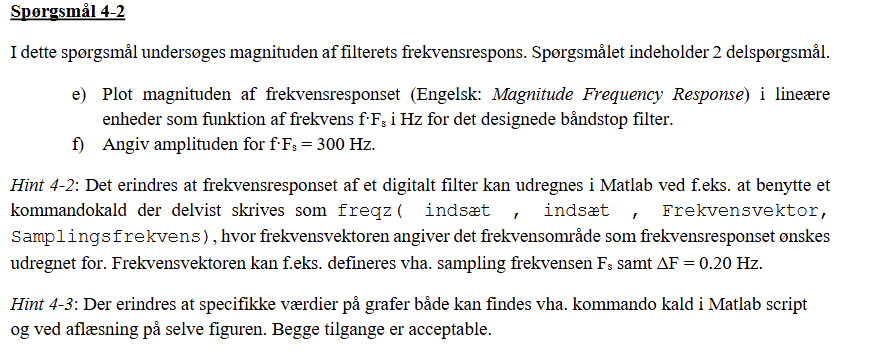

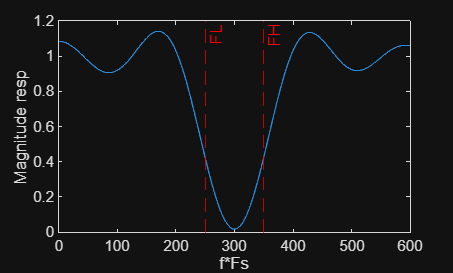


[Hz,freqdig] = freqz(h_ideel,1,1024,Fs);

plot(freqdig,abs(Hz))
xlabel("f*Fs");
ylabel("Magnitude resp")
xlim([0,600])
%ylim([-80,10])
xline(fH*Fs,'--r', "FH")
xline(fL*Fs,'--r', "FL")
hold off

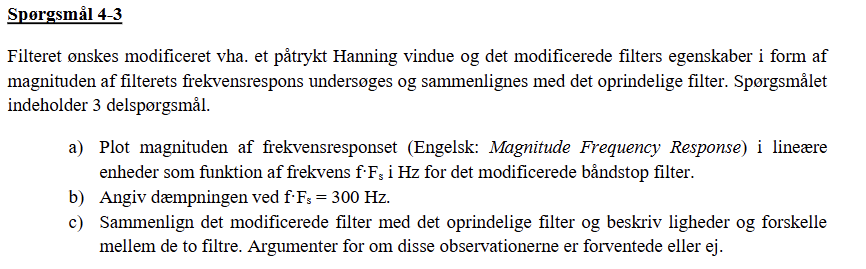


    % vi definerer n_hanning og hanning vinduet
    n_hanning = [0:1:M];
    w_hanning = 0.5-0.5*cos((2*pi*n_hanning)/M)

w_hanning =          0    0.0170    0.0670    0.1464    0.2500    0.3706    0.5000    0.6294    0.7500    0.8536    0.9330    0.9830    1.0000    0.9830    0.9330    0.8536    0.7500    0.6294    0.5000    0.3706    0.2500    0.1464    0.0670    0.0170         0


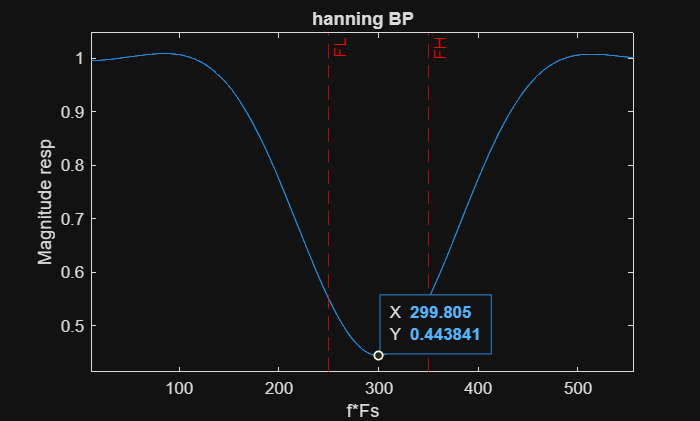

    
    %vi ganger 
    h_w = h_ideel .* w_hanning;
    
    [HHan,freqdig] = freqz(h_w,1,1024,Fs);
    
    plot(freqdig,abs(HHan))
    xlabel("f*Fs");
    ylabel("Magnitude resp")
    title('hanning BP')
    xlim([0,600])
    %ylim([-80,10])
    xline(fH*Fs,'--r', "FH")
    xline(fL*Fs,'--r', "FL")
    hold off